k1 = zeros(5,2);
k1(1,1) = 1;
k1(2,2) = 1;
k2 = zeros(5,3);
k2(3,1) = 1;
k2(4,2) = 1;
k2(5,3) = 1;

k4 = k1-k2*inv(Koo)*Kot;

k6 = zeros(2,5);% 输入5维位移，取其中物理子结构的位移和转角
k6(1,4) = 1;
k6(2,2) = -1;

Hs1 = [1,-0.2954*sin(-0.4444);1,-0.2954*sin(0.4444)]*1e3;
Hs2 = [0.5,0.5;1/(0.5908*sin(0.4444)),-1/(0.5908*sin(0.4444))]*1e-3;

bode图

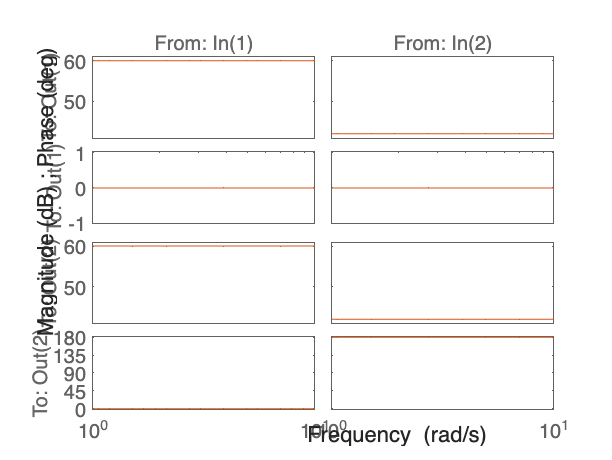

bode(ss(Hs1),tf(Hs1))

单位激励下的响应

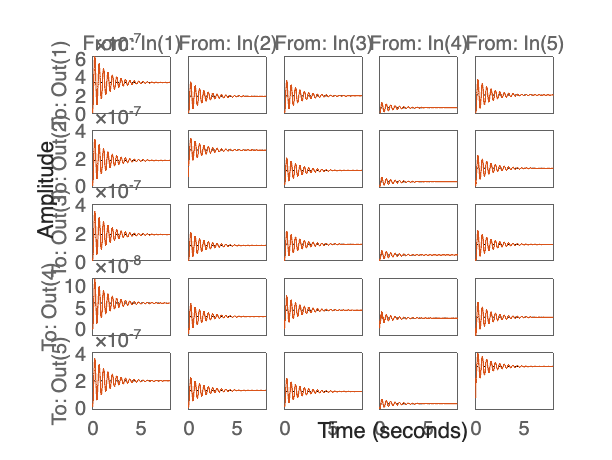

step(Gnd_ss,Gnd_tf)